%% ============================================================
%  MAIN SCRIPT
%  ------------------------------------------------------------
%  Project name   : Tube MPC optimization with neural network
%  Author         : Bene Ádám
%  Date           : 2026.04.28.
%  Description    : Main execution script that calls the required submodules and processing steps.
%  Note           : Run this file directly.
%% ============================================================
clear;
% reference path define for the controller
run("path_define.mlx")

Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.
Számolás: Pálya generálás...
Figyelem: Legalább 3 pont kell!


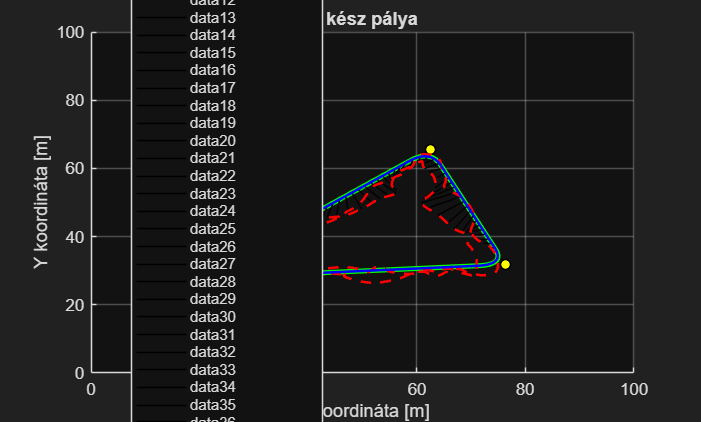

=== 2. FÁZIS: CasADi MPC Szimuláció és Adatgyűjtés ===
CasADi szimuláció fut... (az IPOPT megoldó dolgozik)
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  47.00us (  5.22us)         9
       nlp_g  |        0 (       0) 134.00us ( 14.89us)         9
  nlp_grad_f  |        0 (       0)  47.00us (  4.70us)        10
  nlp_hess_l  |        0 (       0)  32.00us (  4.00us)         8
   nlp_jac_g  |        0 (       0)  51.00us (  5.10us)        10
       total  |   1.98 s (  1.98 s)   1.98 s (  1.98 s)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  42.00us (  5.25us)         8
       nlp_g  |        0 (       0)  69.00us (  8.62us)         8
  nlp_grad_f  |        0 (       0)  51.00us (  5.67us)         9
  nlp_hess_l  |        0 (       0)  28.00us (  4.00us)         7
   nlp_jac_g  |   1.00ms (111.11us)  52.00us (  5.78us)         9
       total  |  27.00ms ( 27.00ms

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  58.00us (  9.67us)         6
       nlp_g  |        0 (       0)  65.00us ( 10.83us)         6
  nlp_grad_f  |        0 (       0)  32.00us (  4.57us)         7
  nlp_hess_l  |        0 (       0)  23.00us (  4.60us)         5
   nlp_jac_g  |        0 (       0)  31.00us (  4.43us)         7
       total  |  25.00ms ( 25.00ms)  24.88ms ( 24.88ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  32.00us (  5.33us)         6
       nlp_g  |        0 (       0)  41.00us (  6.83us)         6
  nlp_grad_f  |        0 (       0)  32.00us (  4.57us)         7
  nlp_hess_l  |        0 (       0)  14.00us (  2.80us)         5
   nlp_jac_g  |        0 (       0)  24.00us (  3.43us)         7
       total  |  20.00ms ( 20.00ms)  19.89ms ( 19.89ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp

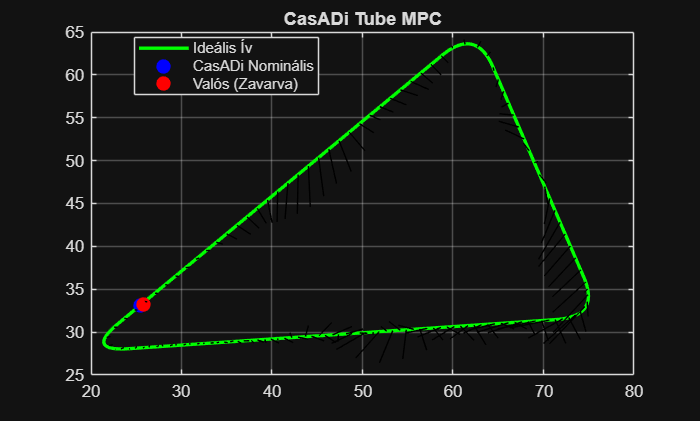


% run tube MPC for previously defined reference path for data gathering
% purposes for further ML training
run("data_gather.mlx")


% DSDE (Dual-Stage Deep Ensemble) with 5-5 neural networks for remaining
% error minimalization, and uncertainty prediction

run("TSDE_train.mlx")

=== Kétlépcsős Deep Ensemble Tanítása Indul ===
--> 1. Fázis: Átlag hálózatok (Ensemble A) tanítása...
    A-Háló 1 / 5...
    A-Háló 2 / 5...
    A-Háló 3 / 5...
    A-Háló 4 / 5...
    A-Háló 5 / 5...
--> Köztes lépés: Zajmérték kiszámítása...
--> 2. Fázis: Bizonytalanság hálózatok (Ensemble B) tanítása...
    B-Háló 1 / 5...
    B-Háló 2 / 5...
    B-Háló 3 / 5...
    B-Háló 4 / 5...
    B-Háló 5 / 5...
=== TANÍTÁS KÉSZ! ===


=== TESZTELÉS INDÍTVA: Klasszikus vs. Hibrid AI ===
--> 1/2. Futás: KLASSZIKUS MPC (Bázis mérés)...
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  57.00us (  4.75us)        12
       nlp_g  |        0 (       0) 187.00us ( 15.58us)        12
  nlp_grad_f  |        0 (       0)  78.00us (  6.00us)        13
  nlp_hess_l  |   2.00ms (181.82us)  45.00us (  4.09us)        11
   nlp_jac_g  |        0 (       0)  69.00us (  5.31us)        13
       total  |  48.00ms ( 48.00ms)  48.33ms ( 48.33ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  65.00us (  5.42us)        12
       nlp_g  |        0 (       0) 165.00us ( 13.75us)        12
  nlp_grad_f  |        0 (       0) 124.00us (  9.54us)        13
  nlp_hess_l  |        0 (       0)  75.00us (  6.82us)        11
   nlp_jac_g  |        0 (       0)  81.00us (  6.23us)        13
       total  |  53.00ms ( 53.00ms)  53.68

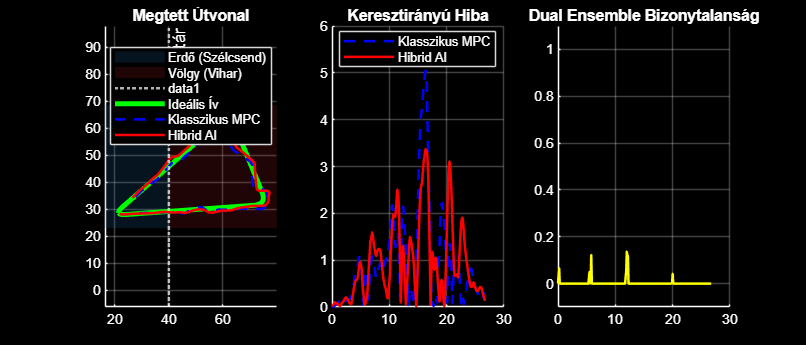


=== VÉGSŐ EREDMÉNYEK ===
Klasszikus Átlag: 0.9678 m
Hibrid AI Átlag:  0.9411 m
JAVULÁS:          +2.8 %


run("TSDE_test.mlx")


%NN+RL combination

% train the first NN from the offline data of the previous simulation for
% deterministic disturbances
%run("train_nn.mlx")

% train a second NN from the offline data of the previous simulation for
% stochastic disturbances
%run("train_sigma_nn.mlx")

%run("ReinforcementLearning.mlx")

%run("hybrid_TubeMPC_test.mlx")


